# **Chauffe-eau électrique avec PV**

clc;
clear;
close all;

## Données

load('dataCESI.mat')
V_max_ballon = 0.150; % m3
V_ec_min = 0.03; % m3
Pelec_bon = 1500; % W
Pelec_boff = 0; % W
C = 4185; % j/Kg
Ti = 10; % T eau froide
Tf = 60; % T eau chaude
Qef = 0;
Qec = 0;
Surplus = zeros(1009,1);
phi = 1500;% --------------------------------------------> 1500 W allumé

## Tracé des heures creuses / heures pleines 

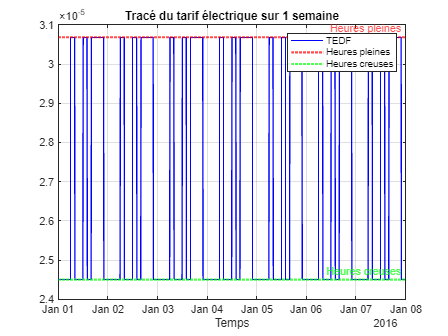

TEDF = TEDF/(1000*6);
figure
plot(t,TEDF,'b')
title('Tracé du tarif électrique sur 1 semaine')
xlabel('Temps')
grid on
yline(3.06833*10^-5,':r','Heures pleines','LineWidth',2)
yline(2.45*10^-5,':g','Heures creuses','LineWidth',2)
legend('TEDF','Heures pleines','Heures creuses')

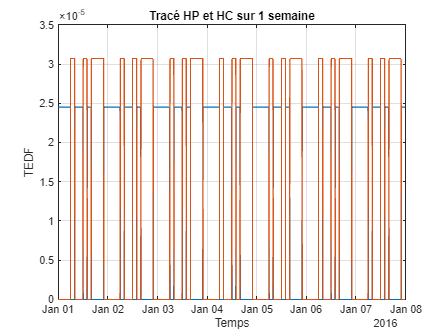

% Heures pleines
HP = zeros(1009,1);
for i = 1:1009
    if TEDF(i) >= 2.46*10^-5
        HP(i) = TEDF(i);
    else
        HP(i) = 0;
    end
end
% Heures creuses
HC = zeros(1009,1);
for i = 1:1009
    if TEDF(i) <= 2.46*10^-5
        HC(i) = TEDF(i);
    else
        HC(i) = 0;
    end
end

figure
plot(t,HC)
hold on
plot(t,HP)
grid on
title('Tracé HP et HC sur 1 semaine')
ylabel('TEDF')
xlabel('Temps')

### Calcul du volume d'eau que l'on peut chauffer sur Te (10 min)

% Calcul du volume d'eau que l'on peut chauffer sur 10 min
% Equation discrétisée => (Vec(k+1) - Vec(k)) / Te = phi / (rho*C*(Tf-Ti)
% On a donc dVec = phi * Te / (rho*C*(Tf-Ti)
Te = 10*60; % en s
rho = 1000; % en Kg/m3
C_Te = phi * Te / (rho*C*(Tf-Ti));
disp(['Si le volume d eau chaude > 0.150 - ',num2str(C_Te)])

Si le volume d eau chaude > 0.150 - 0.0043011


## Stratégie 1:

Nous voulons allumer la résistance uniquement lors des HC, si Vballon < V_max_ballon puis éteindre lorsque Vec = V_max_ballon

### Résistance

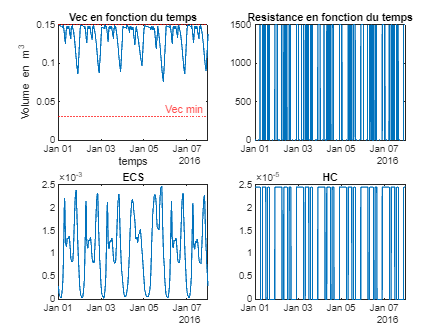

% Calcul de V_ec
Vec = zeros(1009,1);
Vec(1) = 0.150; % m3
Resistance_bool = zeros(1009,1);
Resistance_bool(1) = 0;
% Calcul du fonctionnement de la résistance
Resistance = zeros(1009,1);
for i = 2 : 1009
     if HC(i) > 0 && Vec(i-1) < (0.150 - C_Te)
        Resistance(i) = 1500;
        Resistance_bool(i) = 1;
        Vec(i) = Vec(i-1)+(C_Te * Resistance_bool(i)) - ECS(i);
     else
        Resistance(i) = 0;
        Resistance_bool(i) = 0;
        Vec(i) = Vec(i-1)+(C_Te * Resistance_bool(i)) - ECS(i);
    end
end

% Plot de Vec et Resistance
figure
subplot(2,2,1)
plot(t,Vec)
title('Vec en fonction du temps')
yline(0.15,':r','Vec max')
yline(0.03,':r','Vec min')
ylabel('Volume en m^3')
xlabel('temps')
subplot(2,2,2)
plot(t,Resistance)
title('Resistance en fonction du temps')
subplot(2,2,4)
plot(t,HC)
title('HC')
subplot(2,2,3)
plot(t,ECS)
title('ECS')

### Calcul de la consommation totale d'éléctricité elec + Résistance

% elec_tot consommée
elec_tot = zeros(1009,1);
for i = 1:1009
    elec_tot(i) = elec(i) + Resistance(i);
end

% Utilisation du réseau
Reseau = zeros(1009,1);
for i = 1 : 1009
    if elec_tot(i) - PV(i) > 0
        Reseau(i) = elec_tot(i) - PV(i);
    else
        Reseau(i) = 0;
    end
end

% Autoconsommation %
autocons = zeros(1009,1);
for i = 1:1009
    autocons(i) = PV(i)/elec_tot(i);
    if autocons(i) > 1
        autocons(i) = 1;
    else 
        autocons(i) = PV(i)/elec_tot(i);
    end
end
% Consommation réseau %
Reseaucons = zeros(1009,1);
for i = 1:1009
    Reseaucons(i) = Reseau(i)/elec_tot(i);
end

## Tracé d'elec tot, PV

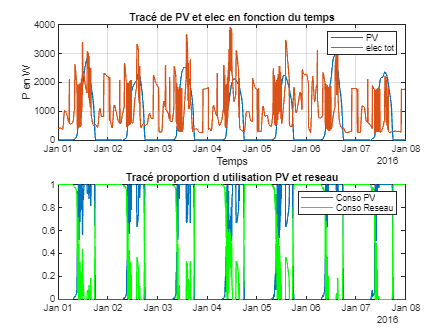

figure
subplot(2,1,1)
plot(t,PV)
hold on
plot(t,elec_tot)
title('Tracé de PV et elec en fonction du temps')
ylabel('P en W')
xlabel('Temps')
legend('PV','elec tot')
grid on
subplot(2,1,2)
plot(t,autocons)
hold on
plot(t,Reseaucons,'g')
legend('Conso PV','Conso Reseau')
title('Tracé proportion d utilisation PV et reseau')

### Calcul de la surproduction PV

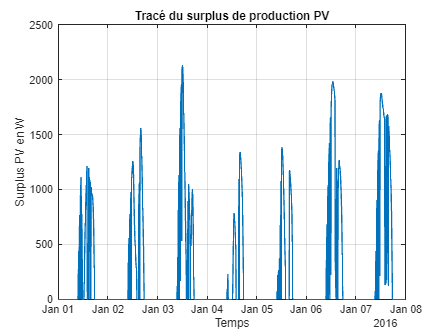

% Boucle du surplus = PV - elec_tot
for i = 1:1009
    Surplus(i) = PV(i) - elec_tot(i);
    if Surplus(i) > 0
        Surplus(i) = Surplus(i);
    else
        Surplus(i) = 0;
    end
end

figure
plot(t,Surplus)
title('Tracé du surplus de production PV')
ylabel('Surplus PV en W')
xlabel('Temps')
grid on

### Tracé de l'utilisation du réseau

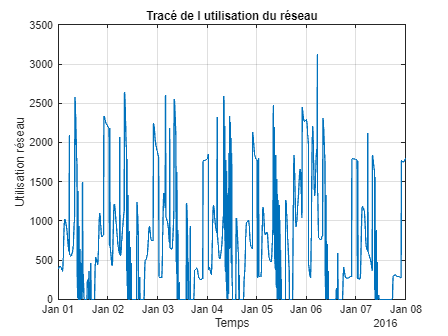

% Boucle du surplus du système PV en % rapport à elec
Reseau = zeros(1009,1);
for i = 1 : 1009
    if elec_tot(i) - PV(i) > 0
        Reseau(i) = elec_tot(i) - PV(i);
    else
        Reseau(i) = 0;
    end
end

figure
plot(t,Reseau)
title('Tracé de l utilisation du réseau')
ylabel('Utilisation réseau')
xlabel('Temps')
grid on

PVcons = zeros(1009,1);
for i = 1:1009
    if PV(i) <= elec_tot(i) 
        PVcons(i) = PV(i);
    else
        PVcons(i) = elec_tot(i);
    end
end

Rautocons1 = sum(PVcons)/sum(PV) *100; % Autoconsommation en %
disp(['L autoconsommation sur une semaine de la stratégie 2 est de : ',num2str(Rautocons1),' %']);

L autoconsommation sur une semaine de la stratégie 2 est de : 60.037 %


Depenses = sum(Reseau.*TEDF);
disp(['Les dépenses pour la stratégie 1 sont de : ',num2str(Depenses),' €'])

Les dépenses pour la stratégie 1 sont de : 19.3431 €


Benefices = sum(Surplus*0.0000167);
disp(['Les bénéfices de la revente du surplus pour la stratégie 1 sont de : ',num2str(Benefices),' €'])

Les bénéfices de la revente du surplus pour la stratégie 1 sont de : 4.1998 €


Facture = Depenses-Benefices;
disp(['La facture pour la semaine est donc de : ',num2str(Facture),' €'])

La facture pour la semaine est donc de : 15.1433 €


cout_watt1 = Depenses/sum(elec_tot);
consow1 = sum(elec_tot)

consow1 = 1.1237e+06

disp(['La facture pour la semaine est donc de : ',num2str(cout_watt1),' €'])

La facture pour la semaine est donc de : 1.7213e-05 €


## Stratégie 2

% Allumer la résistance en heures creuses si le ballon n'est pas plein d'eau
% chaude
% Allumer la résistance en heures pleines si le surplus est suffisant pour que le prix à payer soit inférieur au tarif des heures creuses*
% Allumer la résistance si le volume d'eau chaude est inférieur à 20% du
% volume max (0.03 m3)
% Eteindre la résistance si le ballon a atteint Vec max.

% On reprend la même base que la sratégie 1 mais on doit modifier le calcul
% de fonctionnement de la résistance
% Pseuil=(THP*Pec-Pec*THC)/(THP-Tvente) Pseuil va nous permettre de
% déterminer à quelle niveau de puissance du surplus il est intéressant
% d'allumer la résistance en HP
Pseuil = (1500*0.3068-1500*0.2450)/(0.3068-0.1)

Pseuil = 448.2592

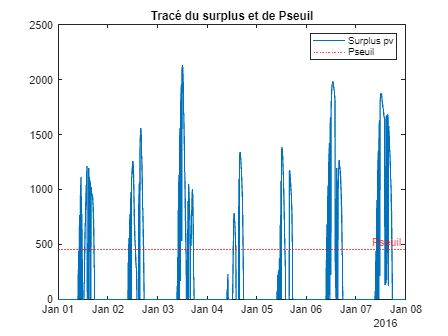

plot(t,Surplus)
yline(abs(Pseuil),':r','Pseuil')
title('Tracé du surplus et de Pseuil')
legend('Surplus pv','Pseuil')

### Résistance

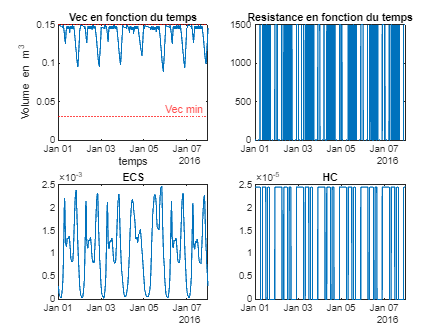

% Calcul de V_ec
Vec = zeros(1009,1);
Vec(1) = 0.150; % m3
Resistance_bool = zeros(1009,1);
Resistance_bool(1) = 0;
HCc = 2.45*10^-5; % constante prix heure creuse
% Calcul du fonctionnement de la résistance
Resistance = zeros(1009,1);
for i = 2 : 1009
     if (HC(i) > 0 && Vec(i-1) < (0.150 - C_Te)) || Surplus(i) >= Pseuil && Vec(i-1) < (0.150 - C_Te)% if (HC(i) > 0 && Vec(i-1) < (0.150 - C_Te)) || ((Reseau(i)*TEDF(i) < elec_tot(i)*HCc) && Vec(i-1) < (0.150 - C_Te))
        Resistance(i) = 1500;
        Resistance_bool(i) = 1;
        Vec(i) = Vec(i-1)+(C_Te * Resistance_bool(i)) - ECS(i);
     else
        Resistance(i) = 0;
        Resistance_bool(i) = 0;
        Vec(i) = Vec(i-1)+(C_Te * Resistance_bool(i)) - ECS(i);
    end
end
% Plot de Vec et Resistance
subplot(2,2,1)
plot(t,Vec)
title('Vec en fonction du temps')
yline(0.15,':r','Vec max')
yline(0.03,':r','Vec min')
ylabel('Volume en m^3')
xlabel('temps')
subplot(2,2,2)
plot(t,Resistance)
title('Resistance en fonction du temps')
subplot(2,2,4)
plot(t,HC)
title('HC')
subplot(2,2,3)
plot(t,ECS)
title('ECS')
hold off

### Calcul de la consommation totale d'éléctricité elec + Résistance

% elec_tot strat 2
elec_tot = zeros(1009,1);
for i = 1:1009
    elec_tot(i) = elec(i) + Resistance(i);
end

% Reseau strat 2
Reseau = zeros(1009,1);
for i = 1 : 1009
    if elec_tot(i) - PV(i) > 0
        Reseau(i) = elec_tot(i) - PV(i);
    else
        Reseau(i) = 0;
    end
end

% Autoconsommation %
autocons = zeros(1009,1);
for i = 1:1009
    autocons(i) = PV(i)/elec_tot(i);
    if autocons(i) > 1
        autocons(i) = 1;
    else 
        autocons(i) = PV(i)/elec_tot(i);
    end
end
% Consommation réseau %
Reseaucons = zeros(1009,1);
for i = 1:1009
    Reseaucons(i) = Reseau(i)/elec_tot(i);
end

## Tracé d'elec tot, PV

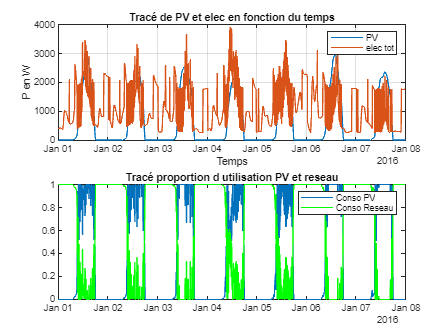

figure
subplot(2,1,1)
plot(t,PV)
hold on
plot(t,elec_tot)
title('Tracé de PV et elec en fonction du temps')
ylabel('P en W')
xlabel('Temps')
legend('PV','elec tot')
grid on
subplot(2,1,2)
plot(t,autocons)
hold on
plot(t,Reseaucons,'g')
legend('Conso PV','Conso Reseau')
title('Tracé proportion d utilisation PV et reseau')

PVcons = zeros(1009,1);
for i = 1:1009
    if PV(i) <= elec_tot(i) 
        PVcons(i) = PV(i);
    else
        PVcons(i) = elec_tot(i);
    end
end

Rautocons2 = sum(PVcons)/sum(PV) *100; % Autoconsommation en %
disp(['L autoconsommation sur une semaine de la stratégie 2 est de : ',num2str(Rautocons2),' %']);

L autoconsommation sur une semaine de la stratégie 2 est de : 63.0776 %



cout_watt2 = Depenses/sum(elec_tot);
disp(['La facture pour la semaine est donc de : ',num2str(cout_watt2),' €'])

La facture pour la semaine est donc de : 1.7167e-05 €


### Calcul de la surproduction PV après utilisation pour le ballon

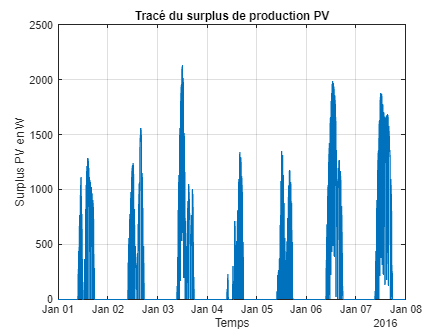

% Boucle du surplus = PV - elec_tot
for i = 1:1009
    Surplus(i) = PV(i) - elec_tot(i);
    if Surplus(i) > 0
        Surplus(i) = Surplus(i);
    else
        Surplus(i) = 0;
    end
end

figure
plot(t,Surplus)
title('Tracé du surplus de production PV')
ylabel('Surplus PV en W')
xlabel('Temps')
grid on

Depenses = sum(Reseau.*TEDF);
disp(['Les dépenses pour la stratégie 2 sont de : ',num2str(Depenses),' €'])

Les dépenses pour la stratégie 2 sont de : 19.069 €


Benefices = sum(Surplus*0.0000167);
disp(['Les bénéfices de la revente du surplus pour la stratégie 2 sont de : ',num2str(Benefices),' €'])

Les bénéfices de la revente du surplus pour la stratégie 2 sont de : 3.8803 €


Facture = Depenses-Benefices;
disp(['La facture pour la semaine est donc de : ',num2str(Facture),' €'])

La facture pour la semaine est donc de : 15.1887 €


### Tracé de l'utilisation du réseau

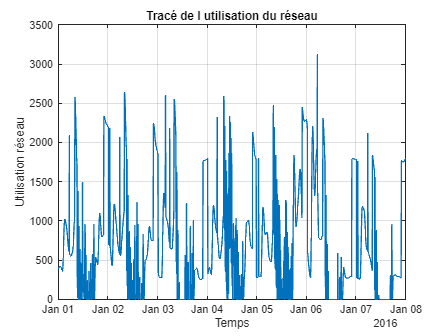

% Boucle du surplus du système PV en % rapport à elec
Reseau = zeros(1009,1);
for i = 1 : 1009
    if elec_tot(i) - PV(i) > 0
        Reseau(i) = elec_tot(i) - PV(i);
    else
        Reseau(i) = 0;
    end
end

figure
plot(t,Reseau)
title('Tracé de l utilisation du réseau')
ylabel('Utilisation réseau')
xlabel('Temps')
grid on

## Coût pour lundi

DepensesL = sum(Reseau(1:144).*TEDF(1:144));
disp(['Les dépenses pour la stratégie 2 lundi sont de : ',num2str(DepensesL),' €'])

Les dépenses pour la stratégie 2 lundi sont de : 2.7537 €


BeneficesL = sum(Surplus(1:144)*0.0000167);
disp(['Les bénéfices de la revente du surplus pour la stratégie 2 sont de : ',num2str(BeneficesL),' €'])

Les bénéfices de la revente du surplus pour la stratégie 2 sont de : 0.45296 €


FactureL = DepensesL-BeneficesL;
disp(['La facture pour la semaine est donc de : ',num2str(FactureL),' €'])

La facture pour la semaine est donc de : 2.3008 €


## Stratégie 3 :

% Rappel de la stratégie 3 :
% Optimisation pour chaque jours de la semaine du  coût grâce au vecteur de
% Pelec
% Respecter les contraintes => Optimisation linéaire avec contraintes
% Contraintes d'inégalité : Vec > 0.03 et Vec < 0.150

% Split time
Lundi = t(1:144,1);
Mardi = t(145:288,1);
Mercredi = t(289:432,1);
Jeudi = t(433:576,1);
Vendredi = t(577:720,1);
Samedi = t(721:864,1);
Dimanche = t(865:end-1,1);

% Split variable
% % Resistance_boolL = Resistance_bool(140,1);
% % elecL = elec(140,1);
% % TEDFL = TEDF(140,1);
% % 
% % % Fonction à minimiser 
% % % Coût = (elec + Resistance_bool*1500)*TEDF à l'instant t sachant que la résistance =
% % % 0 W ou 1500 W il faut mettre le lien entre Resistance et Vec
% % % Je pense à optimisation non linéaire mixte linéaire entier avec contraintes
% % % 1 Variable à optimiser sur 24h le fonctionnement de la résistance
% % x0 = Resistance_boolL;
% % xmin = 0;
% % xmax = 1;
% % fob(x0) = (elecL + Resistance_boolL*1500).*TEDFL;
% % options = optimoptions(@fmincon,'Algorithm','trust-region-reflective','Display','iter','GradObj','on','Hessian','on','PlotFcns',{@optimplotx,@optimplotfunccount,@optimplotfval,@optimplotconstrviolation,@optimplotstepsize,@optimplotfirstorderopt});
% % [x,fval,exitflag,output,grad,hessian] = fmincon(@fob,x0,[],[],[],[],xmin,xmax,[],options)

## Optimisation pour lundi


Single objective optimization:
144 Variables
144 Integer variables
288 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              400          0.1348           12.11        0
    2              590          0.1348           10.39        1
    3              780          0.1348           9.118        2
    4              970          0.1348           8.089        3
    5             1160          0.1348           7.008        4
    6             1350         0.09089           6.132        0
    7             1540         0.09089           5.247        1
    8             1730         0.08239            4.63        0
    9             1920         0.08239           3.926        1
   10      

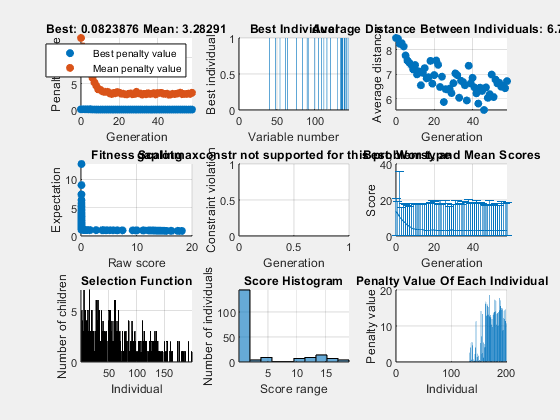

% Initialisation des variables
elecL = elec(1:144);
TEDFL = TEDF(1:144);
Resistance_boolL = Resistance_bool(1:144);
Resistance_boolL = Resistance_boolL';
%global Vend;
Vend = 0.150;

% Nombre de pas de temps
N = length(elecL);

% intcon
intcon = (1:144); % Les 144 valeurs du vecteur à optimiser sont des entiers

% Bornes des variables (Resistance_boolL est un vecteur binaire)
xmin = zeros(N, 1);  % Borne inférieure (0 pour désactiver la résistance)
xmax = ones(N, 1);   % Borne supérieure (1 pour activer la résistance)

options = gaoptimset(@ga);
options.Display = 'iter';
options.MutationFcn = @mutationadaptfeasible;
options.PlotFcns={@gaplotbestf,@gaplotbestindiv,@gaplotdistance,@gaplotexpectation,@gaplotmaxconstr,@gaplotrange,@gaplotselection,@gaplotscorediversity,@gaplotscores};
options.InitialPopulation = Resistance_boolL;  % Utiliser le vecteur trouvé en stratégie 2 comme population initiale

[x,fval,exitflag,output] = ga(@(x) funobj(x),144,[],[],[],[],xmin,xmax,@(x) mycon(x,Vend),intcon,options);

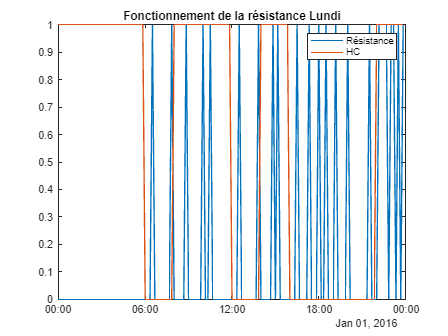


% Récupérer la valeur optimale de Resistance_boolL
Resistance_boolL_optimized = x'; 

% Affichage du fonctionnement de la résistance
HCL=HC(1:144);
HCL_b = HCL > 0;
figure
plot(Lundi,Resistance_boolL_optimized)
hold on
plot(Lundi,HCL_b)
title('Fonctionnement de la résistance Lundi')
legend('Résistance','HC')
hold off


% Coût
cost = funobj(x);
costL = cost;
disp(['Le coût optimisé pour lundi est de ',num2str(cost),' €'])

Le coût optimisé pour lundi est de 2.0593 €


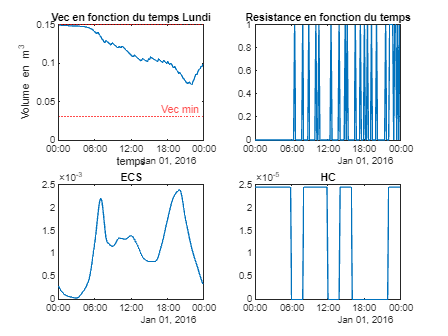


% Calcul de Vec avec le vecteur de fonctionnement de la résistance optimisé pour lundi
% Calcul de V_ec
VecL = zeros(144,1);
VecL(1) = 0.150; % m3
ECSL = ECS(1:144);
PVL = PV(1:144);

% Calcul du volume d'eau chaude dans le ballon
for i = 2:144
    VecL(i) = VecL(i-1) + Resistance_boolL_optimized(i) * C_Te - ECS(i);
end

% Plot de Vec et Resistance
figure
subplot(2,2,1)
plot(Lundi,VecL)
title('Vec en fonction du temps Lundi')
yline(0.15,':r','Vec max')
yline(0.03,':r','Vec min')
ylabel('Volume en m^3')
xlabel('temps')
subplot(2,2,2)
plot(Lundi,Resistance_boolL_optimized)
title('Resistance en fonction du temps')
subplot(2,2,4)
plot(Lundi,HCL)
title('HC')
subplot(2,2,3)
plot(Lundi,ECSL)
title('ECS')
hold off

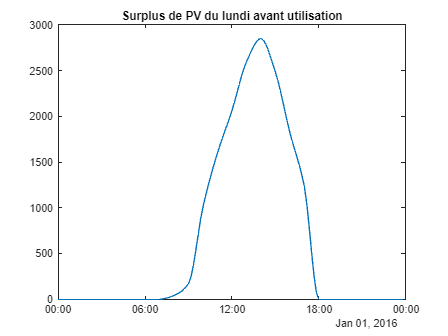


figure
plot(Lundi,PVL)
title('Surplus de PV du lundi avant utilisation')

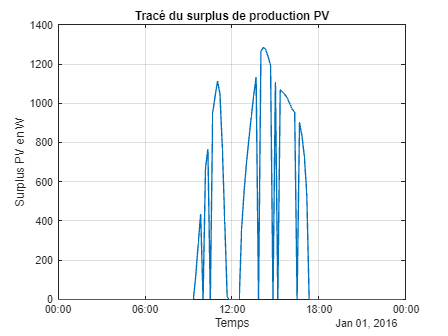


% Surplus
elec_totL = elecL + Resistance_boolL_optimized * 1500;
SurplusL = max(PVL - elec_totL, 0);

figure
plot(Lundi,SurplusL)
title('Tracé du surplus de production PV')
ylabel('Surplus PV en W')
xlabel('Temps')
grid on


% Coût du W*10 min
CWL = cost / sum(elec_totL); % Coût du W optimisé
disp(['Le coût du watt *10min optimisé est de :',num2str(CWL),' €'])

Le coût du watt *10min optimisé est de :1.2948e-05 €


## Optimisation pour mardi


Single objective optimization:
144 Variables
144 Integer variables
288 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              400           2.408           8.574        0
    2              600           2.331           7.071        0
    3              800           2.331           5.954        1
    4             1000           2.331           5.671        2
    5             1200           2.331           5.146        3
    6             1400           2.214           4.789        0
    7             1600           2.213            4.43        0
    8             1800           2.191           4.349        0
    9             2000           2.086           2.945        0
   10      

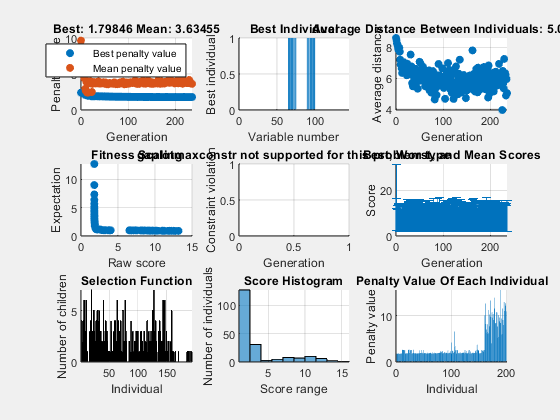

% Initialisation des variables
elecM = elec(145:288);
TEDFM = TEDF(145:288);
Resistance_boolM = Resistance_bool(145:288);
Resistance_boolM = Resistance_boolM';
Vend = VecL(end);
% Nombre de pas de temps
N = length(elecM);

% intcon
intcon = (1:144); % Les 144 valeurs du vecteur à optimiser sont des entiers

% Bornes des variables (Resistance_boolM est un vecteur binaire)
xmin = zeros(N, 1);  % Borne inférieure (0 pour désactiver la résistance)
xmax = ones(N, 1);   % Borne supérieure (1 pour activer la résistance)

options = gaoptimset(@ga);
options.Display = 'iter';
options.MutationFcn = @mutationadaptfeasible;
options.PlotFcns={@gaplotbestf,@gaplotbestindiv,@gaplotdistance,@gaplotexpectation,@gaplotmaxconstr,@gaplotrange,@gaplotselection,@gaplotscorediversity,@gaplotscores};
options.InitialPopulation = Resistance_boolM;  % Utiliser le vecteur trouvé en stratégie 2 comme population initiale

[x,fval,exitflag,output] = ga(@(x) funobj2(x),144,[],[],[],[],xmin,xmax,@(x) mycon(x,Vend),intcon,options);

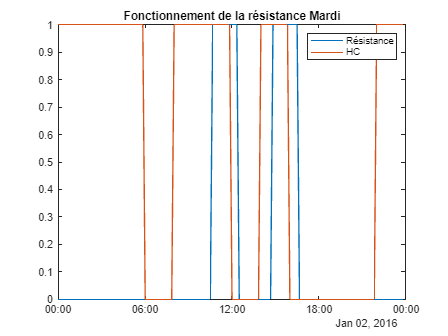


% Récupérer la valeur optimale de Resistance_boolM
Resistance_boolM_optimized = x'; 

% Affichage du fonctionnement de la résistance
HCM=HC(145:288);
HCM_b = HCM > 0;
figure
plot(Mardi,Resistance_boolM_optimized)
hold on
plot(Mardi,HCM_b)
title('Fonctionnement de la résistance Mardi')
legend('Résistance','HC')
hold off


% Coût
cost = funobj2(x);
costM = cost;
disp(['Le coût optimisé pour Mardi est de ',num2str(cost),' €'])

Le coût optimisé pour Mardi est de 1.7985 €


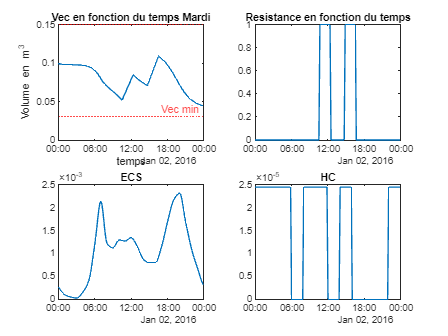


% Calcul de Vec avec le vecteur de fonctionnement de la résistance optimisé pour Mardi
% Calcul de V_ec
VecM = zeros(144,1);
VecM(1) = VecL(end); % m3
ECSM = ECS(145:288);
PVM = PV(145:288);

% Calcul du volume d'eau chaude dans le ballon
for i = 2:144
    VecM(i) = VecM(i-1) + Resistance_boolM_optimized(i) * C_Te - ECSM(i);
end

% Plot de Vec et Resistance
figure
subplot(2,2,1)
plot(Mardi,VecM)
title('Vec en fonction du temps Mardi')
yline(0.15,':r','Vec max')
yline(0.03,':r','Vec min')
ylabel('Volume en m^3')
xlabel('temps')
subplot(2,2,2)
plot(Mardi,Resistance_boolM_optimized)
title('Resistance en fonction du temps')
subplot(2,2,4)
plot(Mardi,HCM)
title('HC')
subplot(2,2,3)
plot(Mardi,ECSM)
title('ECS')
hold off

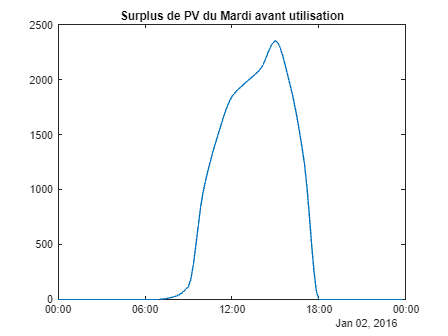


figure
plot(Mardi,PVM)
title('Surplus de PV du Mardi avant utilisation')

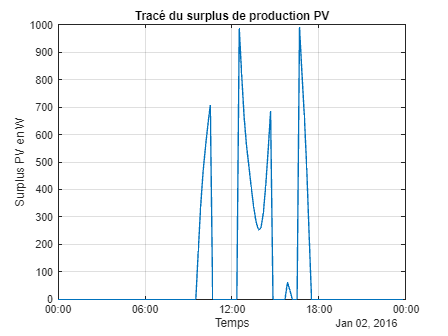


% Surplus
elec_totM = elecM + Resistance_boolM_optimized * 1500;
SurplusM = max(PVM - elec_totM, 0);

figure
plot(Mardi,SurplusM)
title('Tracé du surplus de production PV')
ylabel('Surplus PV en W')
xlabel('Temps')
grid on


% Coût du W*10 min
CWM = cost / sum(elec_totM); % Coût du W optimisé
disp(['Le coût du watt *10min optimisé est de :',num2str(CWL),' €'])

Le coût du watt *10min optimisé est de :1.2948e-05 €


## Optimisation pour mercredi


Single objective optimization:
144 Variables
144 Integer variables
288 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              400           3.103           4.753        0
    2              590           3.103           4.347        1
    3              780           3.012           4.105        0
    4              970           2.962           3.776        0
    5             1160           2.962           3.505        1
    6             1350           2.758            3.68        0    7             1540           2.653           3.259        0
    8             1730           2.597           3.088        0
    9             1920           2.576           2.985        0
   10       

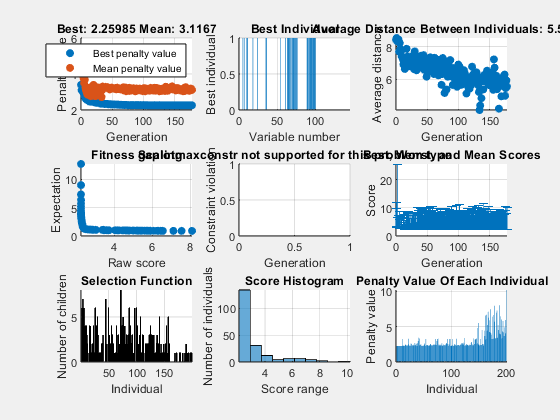

ga stopped because the average change in the penalty function value is less than options.FunctionTolerance and 
the constraint violation is less than options.ConstraintTolerance.


% Initialisation des variables
elecMer = elec(289:432);
TEDFMer = TEDF(289:432);
Resistance_boolMer = Resistance_bool(289:432);
Resistance_boolMer = Resistance_boolMer';
Vend = VecM(end);
% Nombre de pas de temps
N = length(elecMer);

% intcon
intcon = (1:144); % Les 144 valeurs du vecteur à optimiser sont des entiers

% Bornes des variables (Resistance_boolMer est un vecteur binaire)
xmin = zeros(N, 1);  % Borne inférieure (0 pour désactiver la résistance)
xmax = ones(N, 1);   % Borne supérieure (1 pour activer la résistance)

options = gaoptimset(@ga);
options.Display = 'iter';
options.MutationFcn = @mutationadaptfeasible;
options.PlotFcns={@gaplotbestf,@gaplotbestindiv,@gaplotdistance,@gaplotexpectation,@gaplotmaxconstr,@gaplotrange,@gaplotselection,@gaplotscorediversity,@gaplotscores};
options.InitialPopulation = Resistance_boolMer;  % Utiliser le vecteur trouvé en stratégie 2 comme population initiale
        
[x,fval,exitflag,output] = ga(@(x) funobj3(x),144,[],[],[],[],xmin,xmax,@(x) mycon(x,Vend),intcon,options);

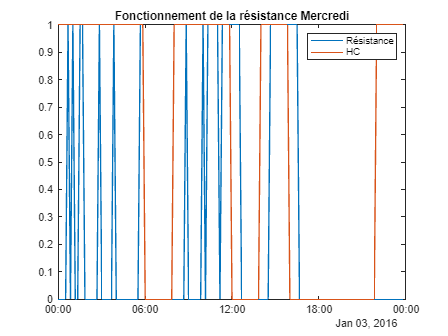


% Récupérer la valeur optimale de Resistance_boolMer
Resistance_boolMer_optimized = x'; 

% Affichage du fonctionnement de la résistance
HCMer=HC(289:432);
HCMer_b = HCMer > 0;
figure
plot(Mercredi,Resistance_boolMer_optimized)
hold on
plot(Mercredi,HCMer_b)
title('Fonctionnement de la résistance Mercredi')
legend('Résistance','HC')
hold off


% Coût
cost = funobj3(x);
costMer = cost;
disp(['Le coût optimisé pour Mercredi est de ',num2str(cost),' €'])

Le coût optimisé pour Mercredi est de 2.2599 €


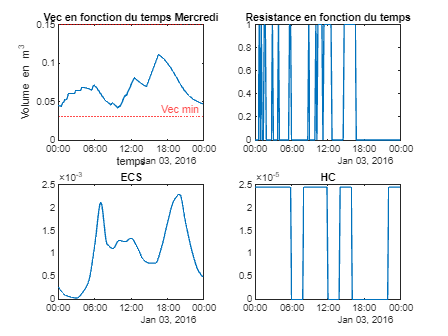


% Calcul de Vec avec le vecteur de fonctionnement de la résistance optimisé pour Mercredi
% Calcul de V_ec
VecMer = zeros(144,1);
VecMer(1) = VecM(end); % m3
ECSMer = ECS(289:432);
PVMer = PV(289:432);

% Calcul du volume d'eau chaude dans le ballon
for i = 2:144
    VecMer(i) = VecMer(i-1) + Resistance_boolMer_optimized(i) * C_Te - ECSMer(i);
end

% Plot de Vec et Resistance
figure
subplot(2,2,1)
plot(Mercredi,VecMer)
title('Vec en fonction du temps Mercredi')
yline(0.15,':r','Vec max')
yline(0.03,':r','Vec min')
ylabel('Volume en m^3')
xlabel('temps')
subplot(2,2,2)
plot(Mercredi,Resistance_boolMer_optimized)
title('Resistance en fonction du temps')
subplot(2,2,4)
plot(Mercredi,HCMer)
title('HC')
subplot(2,2,3)
plot(Mercredi,ECSMer)
title('ECS')
hold off

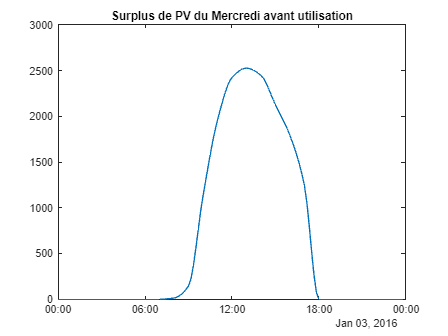


figure
plot(Mercredi,PVMer)
title('Surplus de PV du Mercredi avant utilisation')

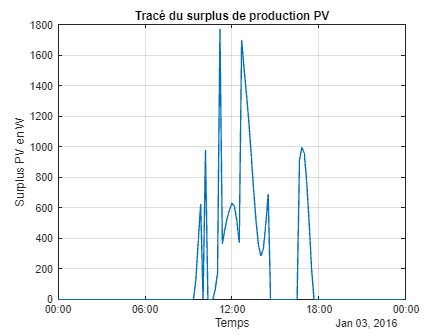


% Surplus
elec_totMer = elecMer + Resistance_boolMer_optimized * 1500;
SurplusMer = max(PVMer - elec_totMer, 0);

figure
plot(Mercredi,SurplusMer)
title('Tracé du surplus de production PV')
ylabel('Surplus PV en W')
xlabel('Temps')
grid on


% Coût du W*10 min
CWMer = cost / sum(elec_totMer); % Coût du W optimisé
disp(['Le coût du watt *10min optimisé est de :',num2str(CWMer),' €'])

Le coût du watt *10min optimisé est de :1.5229e-05 €


## Optimisation pour jeudi


Single objective optimization:
144 Variables
144 Integer variables
288 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              400           3.451           5.134        0
    2              600           3.409            4.65        0
    3              800           3.342           4.261        0
    4             1000           3.306           4.059        0
    5             1200           3.047           3.766        0
    6             1400           2.996            3.58        0
    7             1600            2.89           3.472        0
    8             1800           2.842           3.346        0
    9             2000           2.762           3.261        0
   10      

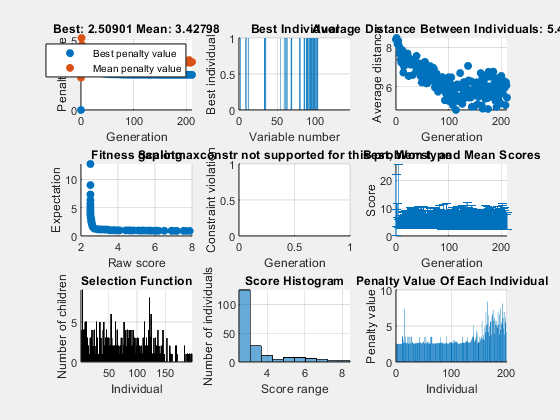

ga stopped because the average change in the penalty function value is less than options.FunctionTolerance and 
the constraint violation is less than options.ConstraintTolerance.


% Initialisation des variables
elecJeu = elec(433:576);
TEDFJeu = TEDF(433:576);
Resistance_boolJeu = ones(144,1);%Resistance_bool(433:576);
Resistance_boolJeu = Resistance_boolJeu';
Vend = VecMer(end);
% Nombre de pas de temps
N = length(elecJeu);

% intcon
intcon = (1:144); % Les 144 valeurs du vecteur à optimiser sont des entiers

% Bornes des variables (Resistance_boolJeu est un vecteur binaire)
xmin = zeros(N, 1);  % Borne inférieure (0 pour désactiver la résistance)
xmax = ones(N, 1);   % Borne supérieure (1 pour activer la résistance)

options = gaoptimset(@ga);
options.Display = 'iter';
options.MutationFcn = @mutationadaptfeasible;
options.PlotFcns={@gaplotbestf,@gaplotbestindiv,@gaplotdistance,@gaplotexpectation,@gaplotmaxconstr,@gaplotrange,@gaplotselection,@gaplotscorediversity,@gaplotscores};
options.InitialPopulation = Resistance_boolJeu;  % Utiliser le vecteur trouvé en stratégie 2 comme population initiale
        
[x,fval,exitflag,output] = ga(@(x) funobj4(x),144,[],[],[],[],xmin,xmax,@(x) mycon(x,Vend),intcon,options);

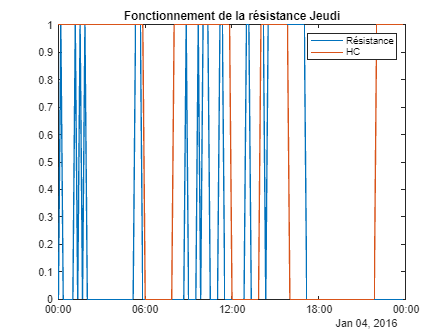


% Récupérer la valeur optimale de Resistance_boolJeu
Resistance_boolJeu_optimized = x'; 

% Affichage du fonctionnement de la résistance
HCJeu=HC(433:576);
HCJeu_b = HCJeu > 0;
figure
plot(Jeudi,Resistance_boolJeu_optimized)
hold on
plot(Jeudi,HCJeu_b)
title('Fonctionnement de la résistance Jeudi')
legend('Résistance','HC')
hold off


% Coût
cost = funobj4(x);
costJeu = cost;
disp(['Le coût optimisé pour Jeudi est de ',num2str(cost),' €'])

Le coût optimisé pour Jeudi est de 2.509 €


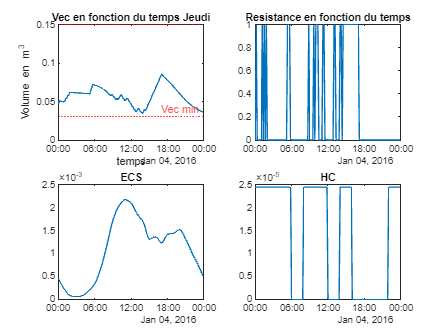


% Calcul de Vec avec le vecteur de fonctionnement de la résistance optimisé pour Jeudi
% Calcul de V_ec
VecJeu = zeros(144,1);
VecJeu(1) = VecMer(end); % m3
ECSJeu = ECS(433:576);
PVJeu = PV(433:576);

% Calcul du volume d'eau chaude dans le ballon
for i = 2:144
    VecJeu(i) = VecJeu(i-1) + Resistance_boolJeu_optimized(i) * C_Te - ECSJeu(i);
end

% Plot de Vec et Resistance
figure
subplot(2,2,1)
plot(Jeudi,VecJeu)
title('Vec en fonction du temps Jeudi')
yline(0.15,':r','Vec max')
yline(0.03,':r','Vec min')
ylabel('Volume en m^3')
xlabel('temps')
subplot(2,2,2)
plot(Jeudi,Resistance_boolJeu_optimized)
title('Resistance en fonction du temps')
subplot(2,2,4)
plot(Jeudi,HCJeu)
title('HC')
subplot(2,2,3)
plot(Jeudi,ECSJeu)
title('ECS')
hold off

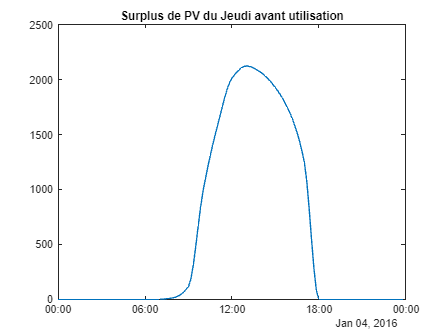


figure
plot(Jeudi,PVJeu)
title('Surplus de PV du Jeudi avant utilisation')

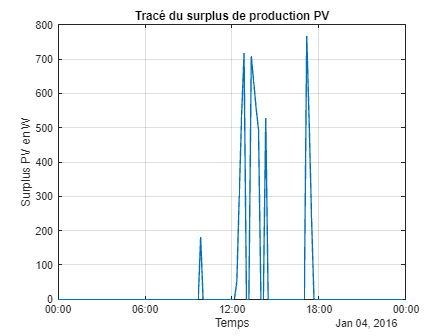


% Surplus
elec_totJeu = elecJeu + Resistance_boolJeu_optimized * 1500;
SurplusJeu = max(PVJeu - elec_totJeu, 0);

figure
plot(Jeudi,SurplusJeu)
title('Tracé du surplus de production PV')
ylabel('Surplus PV en W')
xlabel('Temps')
grid on


% Coût du W*10 min
CWJeu = cost / sum(elec_totJeu); % Coût du W optimisé
disp(['Le coût du watt *10min optimisé est de :',num2str(CWJeu),' €'])

Le coût du watt *10min optimisé est de :1.4328e-05 €


## Optimisation pour vendredi

% Initialisation des variables
elecVen = elec(577:720);
TEDFVen = TEDF(577:720);
Resistance_boolVen = Resistance_bool(577:720);
Resistance_boolVen = Resistance_boolVen';
Vend = VecJeu(end)

Vend = 0.0365


Single objective optimization:
144 Variables
144 Integer variables
288 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              400        0.003541           1.133        0
    2              590        0.003541          0.5304        1
    3              780        0.003541          0.4593        2
    4              970        0.003541          0.4248        3
    5             1160        0.003541          0.3656        4    6             1350        0.003541          0.3668        5
    7             1540        0.003541          0.3604        6
    8             1730        0.003541           0.396        7
    9             1920        0.003541          0.3557        8   10        

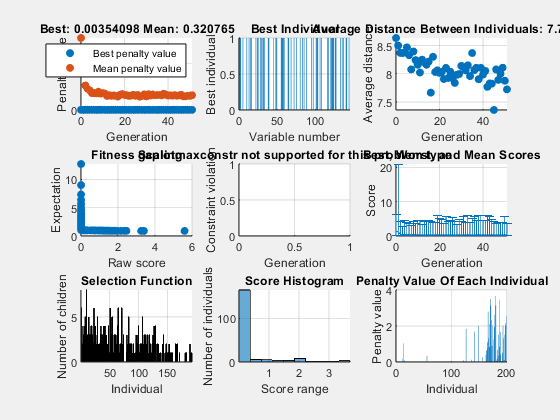

% Nombre de pas de temps
N = length(elecVen);

% intcon
intcon = (1:144); % Les 144 valeurs du vecteur à optimiser sont des entiers

% Bornes des variables (Resistance_boolVen est un vecteur binaire)
xmin = zeros(N, 1);  % Borne inférieure (0 pour désactiver la résistance)
xmax = ones(N, 1);   % Borne supérieure (1 pour activer la résistance)

options = gaoptimset(@ga);
options.Display = 'iter';
options.MutationFcn = @mutationadaptfeasible;
options.PlotFcns={@gaplotbestf,@gaplotbestindiv,@gaplotdistance,@gaplotexpectation,@gaplotmaxconstr,@gaplotrange,@gaplotselection,@gaplotscorediversity,@gaplotscores};
options.InitialPopulation = Resistance_boolVen;  % Utiliser le vecteur trouvé en stratégie 2 comme population initiale
        
[x,fval,exitflag,output] = ga(@(x) funobj5(x),144,[],[],[],[],xmin,xmax,@(x) mycon(x,Vend),intcon,options);

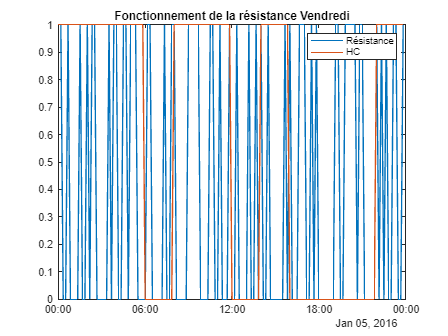


% Récupérer la valeur optimale de Resistance_boolVen
Resistance_boolVen_optimized = x'; 

% Affichage du fonctionnement de la résistance
HCVen=HC(577:720);
HCVen_b = HCVen > 0;
figure
plot(Vendredi,Resistance_boolVen_optimized)
hold on
plot(Vendredi,HCVen_b)
title('Fonctionnement de la résistance Vendredi')
legend('Résistance','HC')
hold off


% Coût
cost = funobj5(x);
costVen = cost;
disp(['Le coût optimisé pour Vendredi est de ',num2str(cost),' €'])

Le coût optimisé pour Vendredi est de 3.8253 €


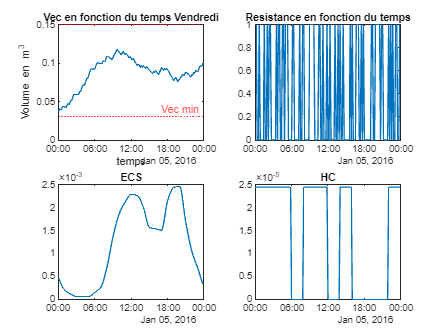


% Calcul de Vec avec le vecteur de fonctionnement de la résistance optimisé pour Vendredi
% Calcul de V_ec
VecVen = zeros(144,1);
VecVen(1) = VecJeu(end); % m3
ECSVen = ECS(577:720);
PVVen = PV(577:720);

% Calcul du volume d'eau chaude dans le ballon
for i = 2:144
    VecVen(i) = VecVen(i-1) + Resistance_boolVen_optimized(i) * C_Te - ECSVen(i);
end

% Plot de Vec et Resistance
figure
subplot(2,2,1)
plot(Vendredi,VecVen)
title('Vec en fonction du temps Vendredi')
yline(0.15,':r','Vec max')
yline(0.03,':r','Vec min')
ylabel('Volume en m^3')
xlabel('temps')
subplot(2,2,2)
plot(Vendredi,Resistance_boolVen_optimized)
title('Resistance en fonction du temps')
subplot(2,2,4)
plot(Vendredi,HCVen)
title('HC')
subplot(2,2,3)
plot(Vendredi,ECSVen)
title('ECS')
hold off

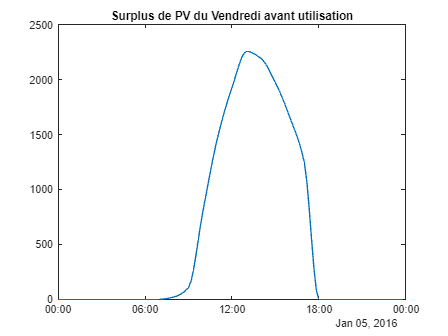


figure
plot(Vendredi,PVVen)
title('Surplus de PV du Vendredi avant utilisation')

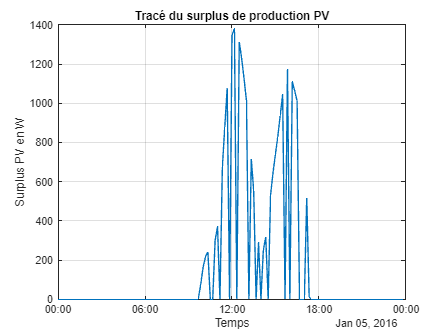


% Surplus
elec_totVen = elecVen + Resistance_boolVen_optimized * 1500;
SurplusVen = max(PVVen - elec_totVen, 0);

figure
plot(Vendredi,SurplusVen)
title('Tracé du surplus de production PV')
ylabel('Surplus PV en W')
xlabel('Temps')
grid on


% Coût du W*10 min
CWVen = cost / sum(elec_totVen); % Coût du W optimisé
disp(['Le coût du watt *10min optimisé est de :',num2str(CWVen),' €'])

Le coût du watt *10min optimisé est de :1.7935e-05 €


## Optimisation pour samedi


Single objective optimization:
144 Variables
144 Integer variables
288 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              400           1.899           7.904        0
    2              590           1.899           6.756        1
    3              780           1.899           6.308        2
    4              970           1.899            5.91        3
    5             1160           1.879           5.388        0
    6             1350           1.879           5.011        1
    7             1540           1.879           4.526        2    8             1730           1.879           4.142        3
    9             1920           1.879           3.885        4
   10       

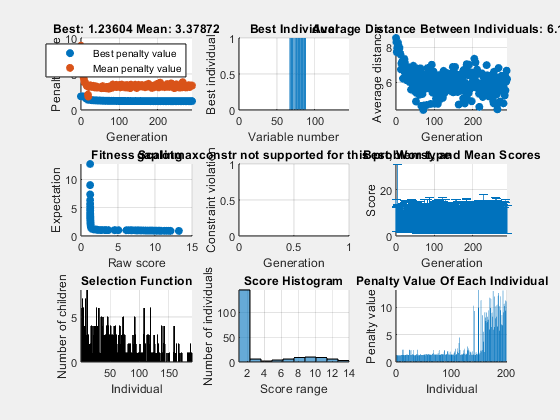

% Initialisation des variables
elecSam = elec(721:864); 
TEDFSam = TEDF(721:864);
Resistance_boolSam = Resistance_bool(721:864);
Resistance_boolSam = Resistance_boolSam';
Vend = VecVen(end);

% Nombre de pas de temps
N = length(elecSam);

% intcon
intcon = (1:144); % Les 144 valeurs du vecteur à optimiser sont des entiers

% Bornes des variables (Resistance_boolSam est un vecteur binaire)
xmin = zeros(N, 1);  % Borne inférieure (0 pour désactiver la résistance)
xmax = ones(N, 1);   % Borne supérieure (1 pour activer la résistance)

options = gaoptimset(@ga);
options.Display = 'iter';
options.MutationFcn = @mutationadaptfeasible;
options.PlotFcns={@gaplotbestf,@gaplotbestindiv,@gaplotdistance,@gaplotexpectation,@gaplotmaxconstr,@gaplotrange,@gaplotselection,@gaplotscorediversity,@gaplotscores};
options.InitialPopulation = Resistance_boolSam;  % Utiliser le vecteur trouvé en stratégie 2 comme population initiale
        
[x,fval,exitflag,output] = ga(@(x) funobj6(x),144,[],[],[],[],xmin,xmax,@(x) mycon(x,Vend),intcon,options);

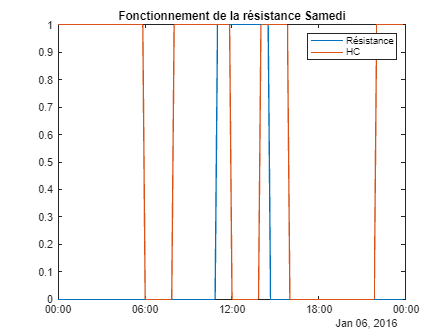


% Récupérer la valeur optimale de Resistance_boolSam
Resistance_boolSam_optimized = x'; 

% Affichage du fonctionnement de la résistance
HCSam=HC(721:864); 
HCSam_b = HCSam > 0;
figure
plot(Samedi,Resistance_boolSam_optimized) % Samedi est à définir
hold on
plot(Samedi,HCSam_b) % Samedi est à définir
title('Fonctionnement de la résistance Samedi')
legend('Résistance','HC')
hold off


% Coût
cost = funobj6(x);
costSam = cost;
disp(['Le coût optimisé pour Samedi est de ',num2str(cost),' €'])

Le coût optimisé pour Samedi est de 1.236 €


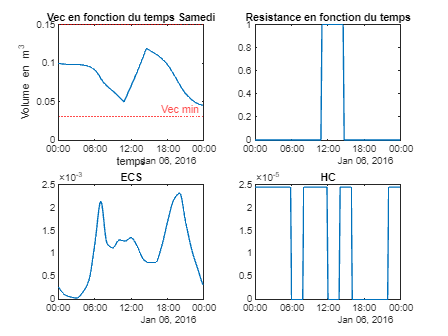


% Calcul de Vec avec le vecteur de fonctionnement de la résistance optimisé pour Samedi
% Calcul de V_ec
VecSam = zeros(144,1);
VecSam(1) = VecVen(end); % m3
ECSSam = ECS(721:864); 
PVSam = PV(721:864); 

% Calcul du volume d'eau chaude dans le ballon
for i = 2:144
    VecSam(i) = VecSam(i-1) + Resistance_boolSam_optimized(i) * C_Te - ECSSam(i);
end

% Plot de Vec et Resistance
figure
subplot(2,2,1)
plot(Samedi,VecSam) % Samedi est à définir
title('Vec en fonction du temps Samedi')
yline(0.15,':r','Vec max')
yline(0.03,':r','Vec min')
ylabel('Volume en m^3')
xlabel('temps')
subplot(2,2,2)
plot(Samedi,Resistance_boolSam_optimized) % Samedi est à définir
title('Resistance en fonction du temps')
subplot(2,2,4)
plot(Samedi,HCSam) % Samedi est à définir
title('HC')
subplot(2,2,3)
plot(Samedi,ECSSam) % Samedi est à définir
title('ECS')
hold off

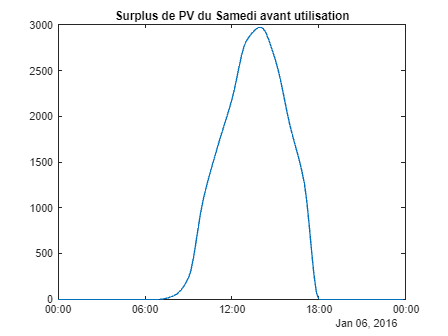


figure
plot(Samedi,PVSam) % Samedi est à définir
title('Surplus de PV du Samedi avant utilisation')

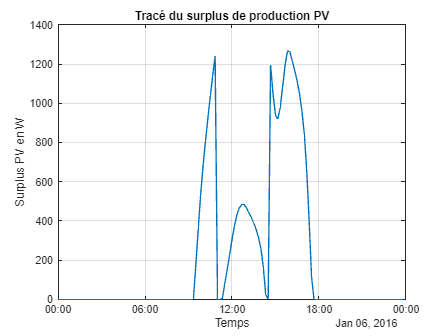


% Surplus
elec_totSam = elecSam + Resistance_boolSam_optimized * 1500;
SurplusSam = max(PVSam - elec_totSam, 0);

figure
plot(Samedi,SurplusSam) % Samedi est à définir
title('Tracé du surplus de production PV')
ylabel('Surplus PV en W')
xlabel('Temps')
grid on


% Coût du W*10 min
CWSam = cost / sum(elec_totSam); % Coût du W optimisé
disp(['Le coût du watt *10min optimisé est de :',num2str(CWSam),' €'])

Le coût du watt *10min optimisé est de :8.9987e-06 €


## Optimisation pour dimanche


Single objective optimization:
144 Variables
144 Integer variables
288 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              400           1.571           3.498        0
    2              600           1.571           2.839        1
    3              800            1.46           2.772        0
    4             1000            1.46           2.127        1
    5             1200           1.424           2.299        0
    6             1400           1.308           1.783        0
    7             1600           1.213           1.649        0
    8             1800           1.213           1.552        1
    9             2000           1.178           1.993        0
   10      

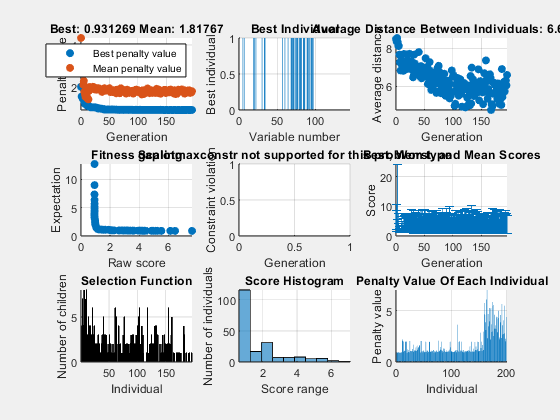

% Initialisation des variables
elecDim = elec(865:end-1);
TEDFDim = TEDF(865:end-1);
Resistance_boolDim = Resistance_bool(865:end-1);
Resistance_boolDim = Resistance_boolDim';
Vend = VecSam(end); 

% Nombre de pas de temps
N = length(elecDim);

% intcon
intcon = (1:144); % Les 144 valeurs du vecteur à optimiser sont des entiers

% Bornes des variables (Resistance_boolDim est un vecteur binaire)
xmin = zeros(N, 1);  % Borne inférieure (0 pour désactiver la résistance)
xmax = ones(N, 1);   % Borne supérieure (1 pour activer la résistance)

options = gaoptimset(@ga);
options.Display = 'iter';
options.MutationFcn = @mutationadaptfeasible;
options.PlotFcns={@gaplotbestf,@gaplotbestindiv,@gaplotdistance,@gaplotexpectation,@gaplotmaxconstr,@gaplotrange,@gaplotselection,@gaplotscorediversity,@gaplotscores};
options.InitialPopulation = Resistance_boolDim;  % Utiliser le vecteur trouvé en stratégie 2 comme population initiale
        
[x,fval,exitflag,output] = ga(@(x) funobj7(x),144,[],[],[],[],xmin,xmax,@(x) mycon(x,Vend),intcon,options);

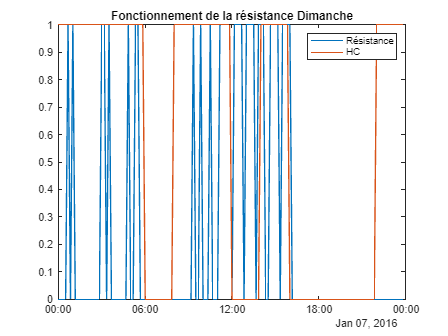


% Récupérer la valeur optimale de Resistance_boolDim
Resistance_boolDim_optimized = x'; 

% Affichage du fonctionnement de la résistance
HCDim=HC(865:end-1);
HCDim_b = HCDim > 0;
figure
plot(Dimanche,Resistance_boolDim_optimized)
hold on
plot(Dimanche,HCDim_b)
title('Fonctionnement de la résistance Dimanche')
legend('Résistance','HC')
hold off

% Coût
cost = funobj7(x);
costDim = cost;
disp(['Le coût optimisé pour Dimanche est de ',num2str(cost),' €'])

Le coût optimisé pour Dimanche est de 0.93127 €


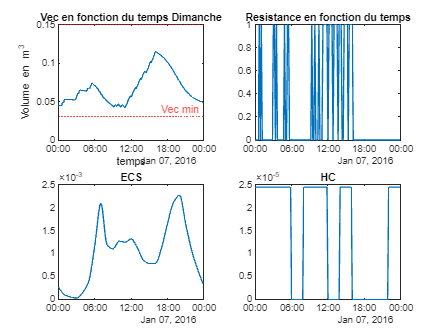

% Calcul de Vec avec le vecteur de fonctionnement de la résistance optimisé pour Dimanche
% Calcul de V_ec
VecDim = zeros(144,1);
VecDim(1) = VecSam(end); % m3
ECSDim = ECS(865:end-1);
PVDim = PV(865:end-1);

% Calcul du volume d'eau chaude dans le ballon
for i = 2:144
    VecDim(i) = VecDim(i-1) + Resistance_boolDim_optimized(i) * C_Te - ECSDim(i);
end

% Plot de Vec et Resistance
figure
subplot(2,2,1)
plot(Dimanche,VecDim)
title('Vec en fonction du temps Dimanche')
yline(0.15,':r','Vec max')
yline(0.03,':r','Vec min')
ylabel('Volume en m^3')
xlabel('temps')
subplot(2,2,2)
plot(Dimanche,Resistance_boolDim_optimized)
title('Resistance en fonction du temps')
subplot(2,2,4)
plot(Dimanche,HCDim)
title('HC')
subplot(2,2,3)
plot(Dimanche,ECSDim)
title('ECS')
hold off

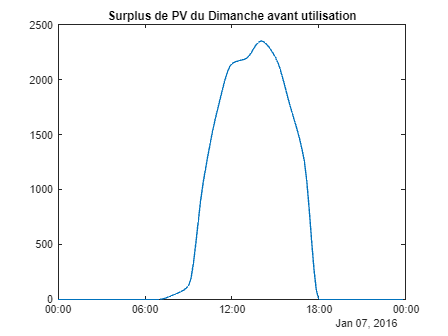

figure
plot(Dimanche,PVDim)
title('Surplus de PV du Dimanche avant utilisation')

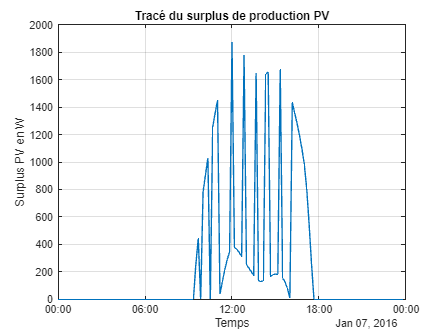

% Surplus
elec_totDim = elecDim + Resistance_boolDim_optimized * 1500;
SurplusDim = max(PVDim - elec_totDim, 0);

figure
plot(Dimanche,SurplusDim)
title('Tracé du surplus de production PV')
ylabel('Surplus PV en W')
xlabel('Temps')
grid on

% Coût du W*10 min
CWDim = cost / sum(elec_totDim); % Coût du W optimisé
disp(['Le coût du watt *10min optimisé est de :',num2str(CWDim),' €'])

Le coût du watt *10min optimisé est de :8.1751e-06 €


Vec_opti_tot = zeros(1008,1)

Vec_opti_tot =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## Total optimisation

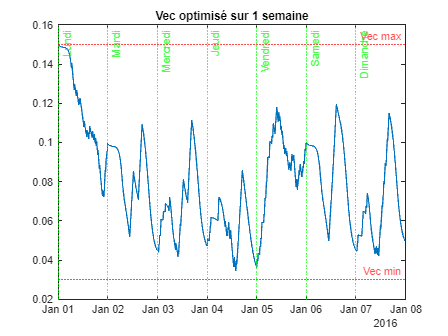

Vec_opti_tot(1:144) = VecL;
Vec_opti_tot(145:288) = VecM;
Vec_opti_tot(289:432) = VecMer;
Vec_opti_tot(433:576) = VecJeu;
Vec_opti_tot(577:720) = VecVen;
Vec_opti_tot(721:864) = VecSam;
Vec_opti_tot(865:end) = VecDim;
figure
plot(t(1:1008),Vec_opti_tot)
title('Vec optimisé sur 1 semaine')
yline(0.03,':r','Vec min');
yline(0.150,':r','Vec max');
xline(0,':g','Lundi')
xline(t(145),':g','Mardi')
xline(t(289),':g','Mercredi')
xline(t(433),':g','Jeudi')
xline(t(577),':g','Vendredi')
xline(t(721),':g','Samedi')
xline(t(865),':g','Dimanche')


% Mettre xline pour voir les jours
Facture_opti = costL+costM+costMer+costJeu+costVen+costSam+costDim

Facture_opti = 14.6193

elec_tot = sum(elec_totL)+sum(elec_totM)+sum(elec_totMer)+sum(elec_totJeu)+sum(elec_totVen)+sum(elec_totSam)+sum(elec_totDim)

elec_tot = 1.0934e+06

cout_watt = Facture_opti/elec_tot;
disp(['Le coût du watt sur 10 min est de : ',num2str(cout_watt),' €'])

Le coût du watt sur 10 min est de : 1.337e-05 €


% PVcons = zeros(1009,1);
% for i = 1:1009
%     if PV(i) <= elec_tot(i) 
%         PVcons(i) = PV(i);
%     else
%         PVcons(i) = elec_tot(i);
%     end
% end
% 
% Rautocons3 = sum(PVcons)/sum(PV) *100; % Autoconsommation en %
% disp(['L autoconsommation sur une semaine de la stratégie 2 est de : ',num2str(Rautocons3),' %']);


% % Initialisation des variables
% elecM = elec(145:288);
% TEDFM = TEDF(145:288);
% ECSM = ECS(145:288);
% elec_totM = elecM + Resistance_boolM_optimized * 1500;
% SurplusM = max(PVM - elec_totM, 0);

% Resistance_boolM = zeros(144,1);
% Resistance_boolM(1) = VecL(end);
% HCM=HC(145:288);
% for i = 2 : 144
%      if (HCM(i) > 0 && VecM(i-1) < (0.150 - C_Te)) || SurplusM(i) >= Pseuil && VecM(i-1) < (0.150 - C_Te)
%         Resistance(i) = 1500;
%         Resistance_boolM(i) = 1;
%         Vec(i) = Vec(i-1)+(C_Te * Resistance_boolM(i)) - ECSM(i);
%      else
%         Resistance(i) = 0;
%         Resistance_boolM(i) = 0;
%         Vec(i) = Vec(i-1)+(C_Te * Resistance_boolM(i)) - ECSM(i);
%     end
% end